clearvars
load OW_OAI_AWS.mat
load OAI_atmos41.mat

## clean up missing vals


atmos41data.WindSpeedms(atmos41data.WindSpeedms<0)=NaN;
atmos41data.WindDirectiondeg(atmos41data.WindDirectiondeg<0)=NaN;
atmos41data.AtmosPressurekPa(atmos41data.AtmosPressurekPa==0)=NaN;

## Daily Resample


T41sum=retime(atmos41data,'daily','sum');
T41mean=retime(atmos41data,'daily','mean');
T41min=retime(atmos41data,'daily','min');
T41max=retime(atmos41data,'daily','max');
% nansum returns 0 if all elements are NaN.  find aggregations where all
% elements are NaN and replace with NaN
allnan=retime(atmos41data,'daily',@(x) all(isnan(x)));
atmos41varnames=atmos41data.Properties.VariableNames;
for i=1:size(atmos41data,2)
    T41sum.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
    T41mean.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
    T41min.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
    T41max.(atmos41varnames{i})(allnan.(atmos41varnames{i}))=NaN;
end


TOWsum=retime(OWdata,'daily','sum');
TOWmean=retime(OWdata,'daily','mean');

## Daily Mins and Max

## Daily time series

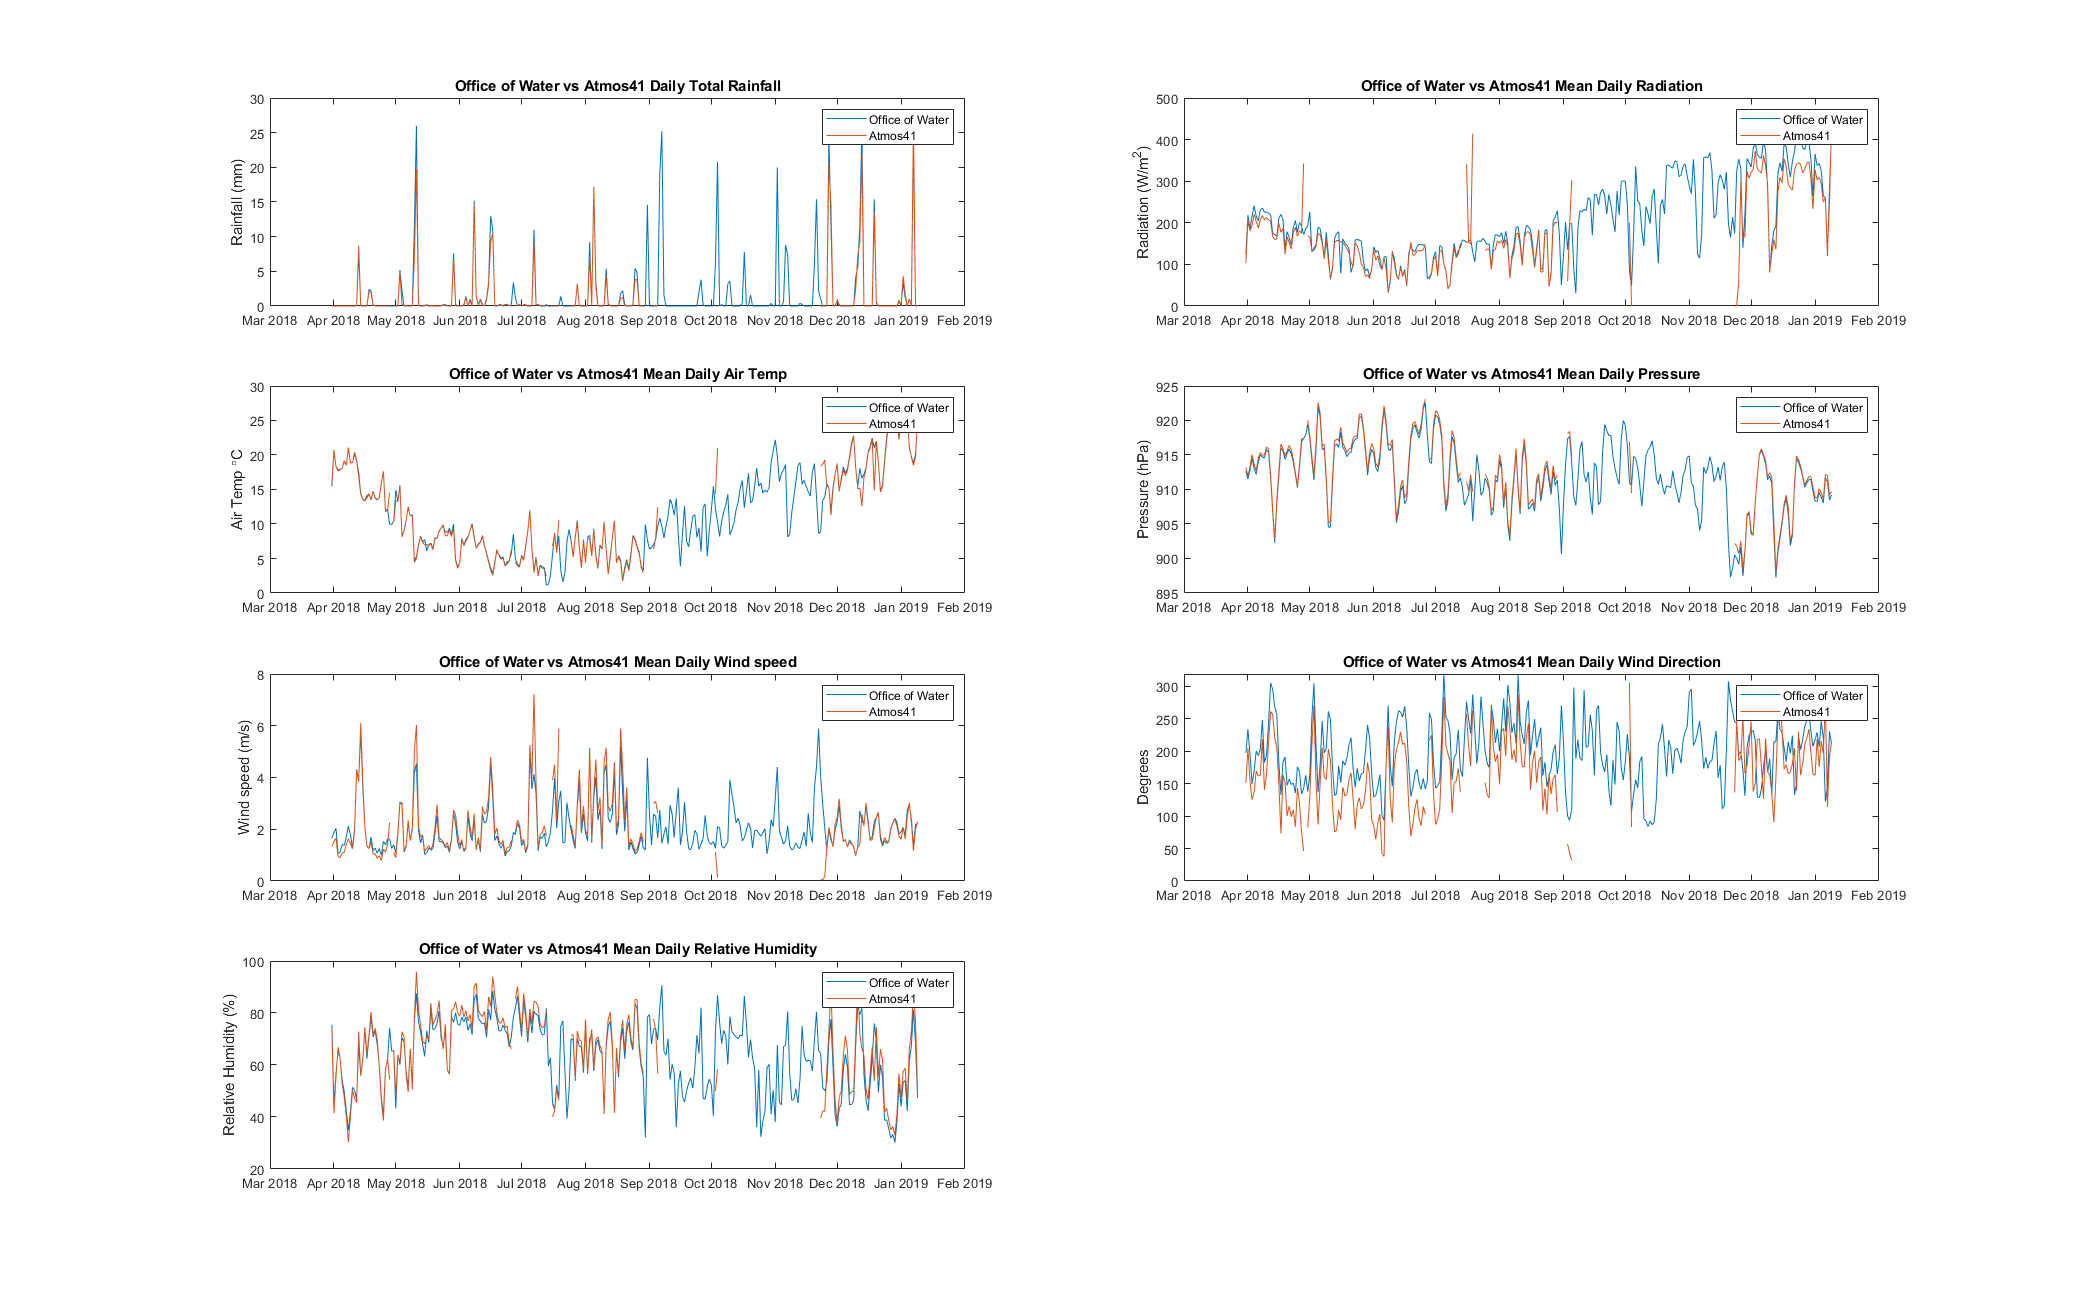


% close all



figure('Position',[242          25        2076        1313])
subplot(4,2,1)
plot(TOWsum.Time,TOWsum.Rainfallmm,T41sum.Timestamps,T41sum.Precipitationmm)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Daily Total Rainfall')
ylabel('Rainfall (mm)')

subplot(4,2,2)
plot(TOWmean.Time,TOWmean.GlobalRadWSqM,T41mean.Timestamps,T41mean.SolarRadiationWm2)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Radiation')
ylabel('Radiation (W/m^2)')

subplot(4,2,3)
plot(TOWmean.Time,TOWmean.AirTemperature,T41mean.Timestamps,T41mean.AirTempdegC)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Air Temp')
ylabel('Air Temp {\circ}C')

subplot(4,2,4)
plot(TOWmean.Time,TOWmean.BaroPressurehPa,T41mean.Timestamps,T41mean.AtmosPressurekPa*10)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Pressure')
ylabel('Pressure (hPa)')

subplot(4,2,5)
plot(TOWmean.Time,TOWmean.AvWindSpeedMs,T41mean.Timestamps,T41mean.WindSpeedms)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Wind speed')
ylabel('Wind speed (m/s)')

subplot(4,2,6)
plot(TOWmean.Time,TOWmean.WindDirDeg,T41mean.Timestamps,T41mean.WindDirectiondeg)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Wind Direction')
ylabel('Degrees')

subplot(4,2,7)
plot(TOWmean.Time,TOWmean.RelativeHumidity,T41mean.Timestamps,T41mean.RelHumidity)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Relative Humidity')
ylabel('Relative Humidity (%)')


print(gcf,'atmos41vOoWtimeseries','-dpng','-r100')

## Correlation plots

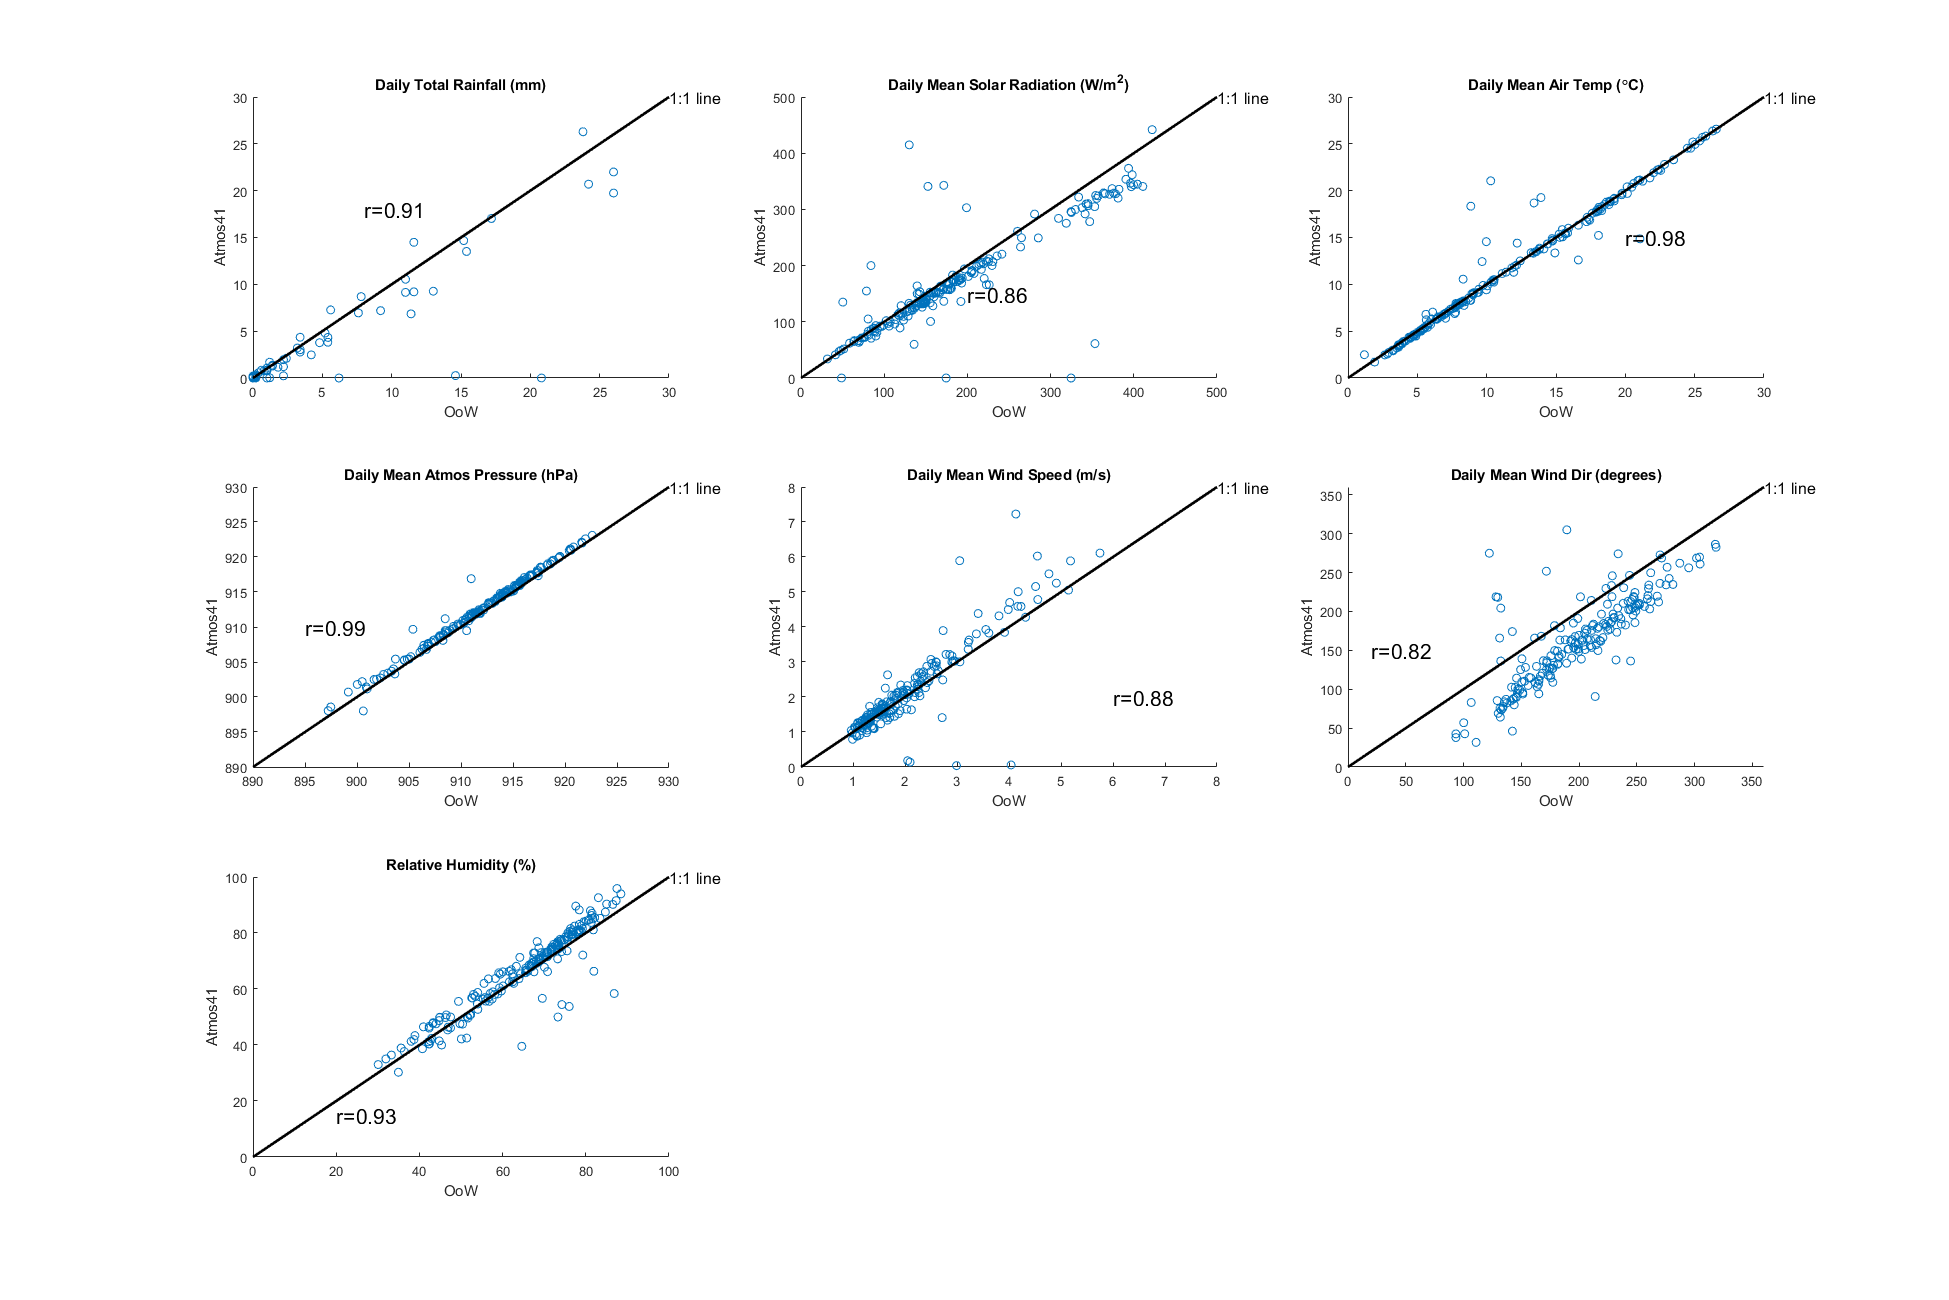


% close all

figure('Position',[498          38        1949        1300])
subplot(3,3,1)
scatter(TOWsum.Rainfallmm,T41sum.Precipitationmm)
title('Daily Total Rainfall (mm)')
hold on
%plot 1:1 line
x=0:30;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,pv]=corrcoef(TOWsum.Rainfallmm,T41sum.Precipitationmm,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
% string2=['p<' num2str(pv(1,2))];
text(8,18,string,'fontsize',16)

xlabel('OoW')
ylabel('Atmos41')
set(gca,'xlim',[ 0 30],'ylim',[ 0 30]);


subplot(3,3,2)
scatter(TOWmean.GlobalRadWSqM,T41mean.SolarRadiationWm2)
title('Daily Mean Solar Radiation (W/m^2)')
hold on
%plot 1:1 line
x=0:500;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,pv]=corrcoef(TOWmean.GlobalRadWSqM,T41mean.SolarRadiationWm2,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
% string2=['p<' num2str(pv(1,2))];
text(200,150,string,'fontsize',16)

xlabel('OoW')
ylabel('Atmos41')
% set(gca,'xlim',[ 0 30],'ylim',[ 0 30]);



subplot(3,3,3)
scatter(TOWmean.AirTemperature,T41mean.AirTempdegC)
title('Daily Mean Air Temp ({\circ}C)')

hold on
%plot 1:1 line
x=0:30;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,pv]=corrcoef(TOWmean.AirTemperature,T41mean.AirTempdegC,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
% string2=['p<' num2str(pv(1,2))];
text(20,15,string,'fontsize',16)

xlabel('OoW')
ylabel('Atmos41')
% set(gca,'xlim',[ 0 30],'ylim',[ 0 30]);


subplot(3,3,4)
scatter(TOWmean.BaroPressurehPa,T41mean.AtmosPressurekPa*10)
title('Daily Mean Atmos Pressure (hPa)')

hold on
%plot 1:1 line
x=890:930;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,pv]=corrcoef(TOWmean.BaroPressurehPa,T41mean.AtmosPressurekPa*10,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
% string2=['p<' num2str(pv(1,2))];
text(895,910,string,'fontsize',16)

xlabel('OoW')
ylabel('Atmos41')
% set(gca,'xlim',[ 0 30],'ylim',[ 0 30]);

subplot(3,3,5)
scatter(TOWmean.AvWindSpeedMs,T41mean.WindSpeedms)
title('Daily Mean Wind Speed (m/s)')

hold on
%plot 1:1 line
x=0:8;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,pv]=corrcoef(TOWmean.AvWindSpeedMs,T41mean.WindSpeedms,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
% string2=['p<' num2str(pv(1,2))];
text(6,2,string,'fontsize',16)

xlabel('OoW')
ylabel('Atmos41')
% set(gca,'xlim',[ 0 30],'ylim',[ 0 30]);

subplot(3,3,6)
scatter(TOWmean.WindDirDeg,T41mean.WindDirectiondeg)
title('Daily Mean Wind Dir (degrees)')

hold on
%plot 1:1 line
x=0:360;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,pv]=corrcoef(TOWmean.WindDirDeg,T41mean.WindDirectiondeg,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
% string2=['p<' num2str(pv(1,2))];
text(20,150,string,'fontsize',16)

xlabel('OoW')
ylabel('Atmos41')
set(gca,'xlim',[ 0 360],'ylim',[ 0 360]);

subplot(3,3,7)
scatter(TOWmean.RelativeHumidity,T41mean.RelHumidity)
title('Relative Humidity (%)')

hold on
%plot 1:1 line
x=0:100;
y=x;
plot(x,y,'k','linewidth',2);
text(max(x),max(y),'1:1 line','fontsize',12)

%calculate r value
[r,pv]=corrcoef(TOWmean.RelativeHumidity,T41mean.RelHumidity,'rows','complete');
Y = sprintf('%.2f',r(1,2));
string=['r=' Y];
% string2=['p<' num2str(pv(1,2))];
text(20,15,string,'fontsize',16)

xlabel('OoW')
ylabel('Atmos41')
% set(gca,'xlim',[ 0 30],'ylim',[ 0 30]);


print(gcf,'atmos41vOoW_correlation','-dpng','-r100')

## Raw time series

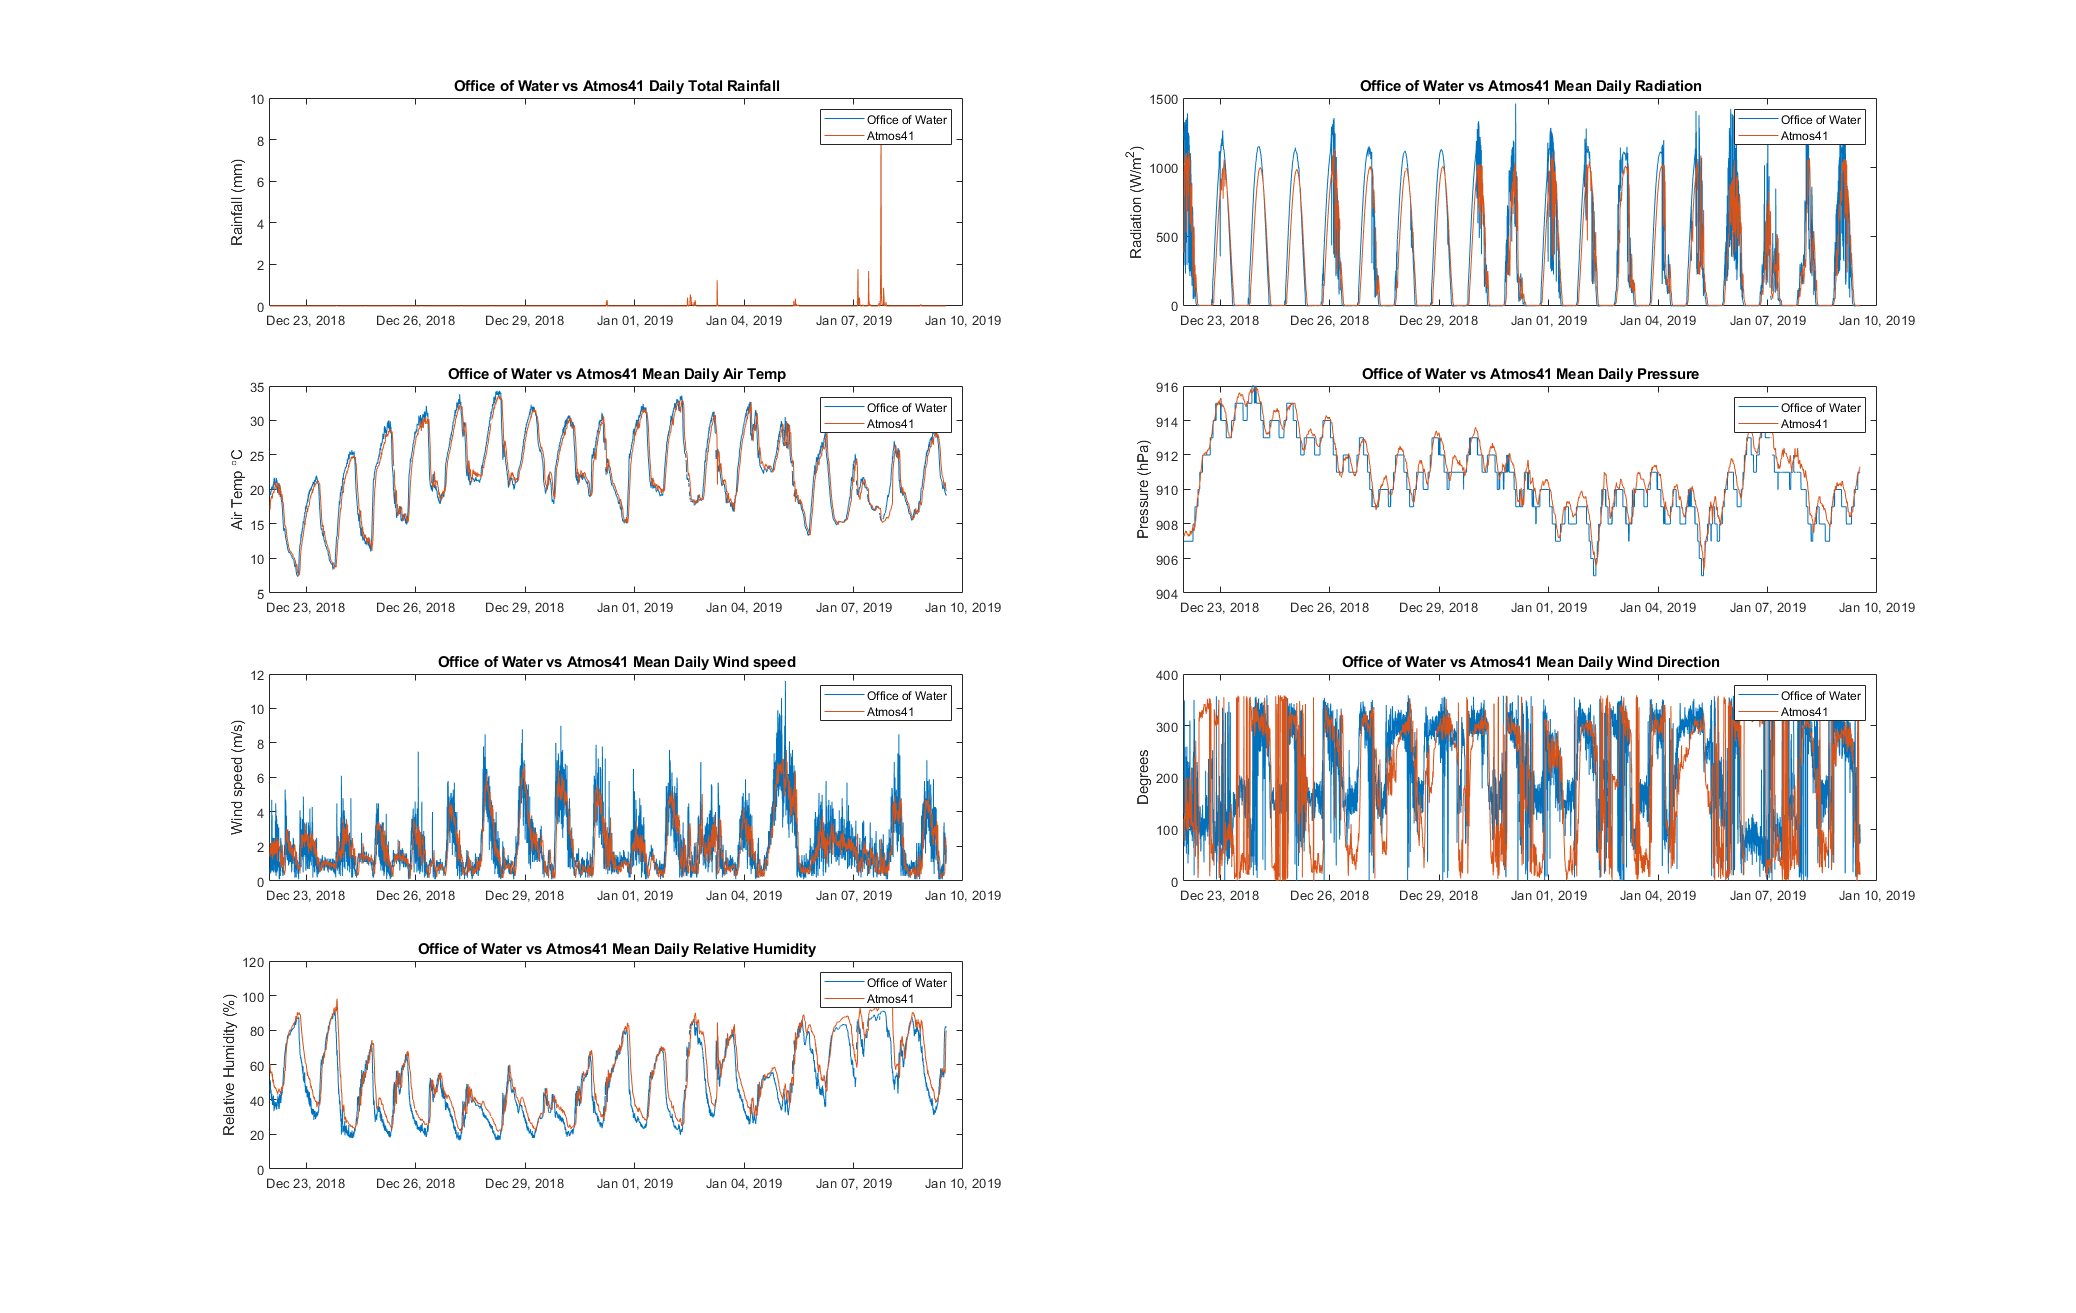



figure('Position',[242          25        2076        1313])
a1=subplot(4,2,1);
plot(OWdata.Time,OWdata.Rainfallmm,atmos41data.Timestamps,atmos41data.Precipitationmm)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Daily Total Rainfall')
ylabel('Rainfall (mm)')

a2=subplot(4,2,2);
plot(OWdata.Time,OWdata.GlobalRadWSqM,atmos41data.Timestamps,atmos41data.SolarRadiationWm2)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Radiation')
ylabel('Radiation (W/m^2)')

a3=subplot(4,2,3);
plot(OWdata.Time,OWdata.AirTemperature,atmos41data.Timestamps,atmos41data.AirTempdegC)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Air Temp')
ylabel('Air Temp {\circ}C')

a4=subplot(4,2,4);
plot(OWdata.Time,OWdata.BaroPressurehPa,atmos41data.Timestamps,atmos41data.AtmosPressurekPa*10)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Pressure')
ylabel('Pressure (hPa)')

a5=subplot(4,2,5);
plot(OWdata.Time,OWdata.AvWindSpeedMs,atmos41data.Timestamps,atmos41data.WindSpeedms)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Wind speed')
ylabel('Wind speed (m/s)')

a6=subplot(4,2,6);
plot(OWdata.Time,OWdata.WindDirDeg,atmos41data.Timestamps,atmos41data.WindDirectiondeg)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Wind Direction')
ylabel('Degrees')

a7=subplot(4,2,7);
plot(OWdata.Time,OWdata.RelativeHumidity,atmos41data.Timestamps,atmos41data.RelHumidity)
legend('Office of Water','Atmos41')
title('Office of Water vs Atmos41 Mean Daily Relative Humidity')
ylabel('Relative Humidity (%)')




linkaxes([a1 a2 a3 a4 a5 a6 a7], 'x')
set(gca,'xlim',[datetime(2018,12,22,'timezone','UTC') datetime(2019,1,10,'timezone','UTC')])


% print(gcf,'atmos41vOoWtimeseries_noresampling','-dpng','-r100')

## Daily Mins and Max

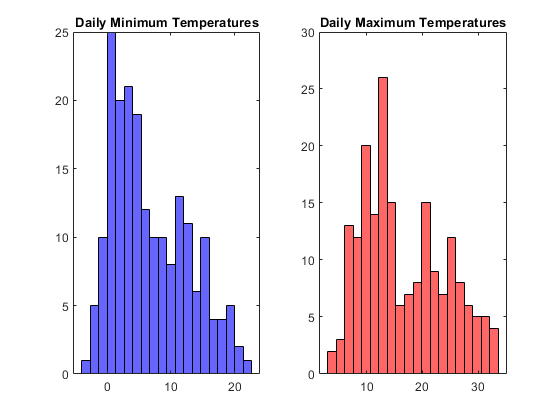



% figure
% plot(T41min.Timestamps, T41min.AirTempdegC,T41max.Timestamps,T41max.AirTempdegC)

figure
subplot(1,2,1)
ph1=histogram(T41min.AirTempdegC,20);
set(ph1,'facecolor','b')
title('Daily Minimum Temperatures')
subplot(1,2,2)
ph2=histogram(T41max.AirTempdegC,20);
set(ph2,'facecolor','r')
title('Daily Maximum Temperatures')